# View Montage of Activations from GoogLeNet

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads GoogLeNet and displays the layers.

net = googlenet;
layers = net.Layers

layers =   144×1 Layer array with layers:

     1   'data'                           Image Input                   224×224×3 images with 'zerocenter' normalization
     2   'conv1-7x7_s2'                   2-D Convolution               64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'conv1-relu_7x7'                 ReLU                          ReLU
     4   'pool1-3x3_s2'                   2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  1  0  1]
     5   'pool1-norm1'                    Cross Channel Normalization   cross channel normalization with 5 channels per element
     6   'conv2-3x3_reduce'               2-D Convolution               64 1×1×64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'conv2-relu_3x3_reduce'          ReLU                          ReLU
     8   'conv2-3x3'                      2-D Convolution           

This code loads the daisy image and displays the first convolution layer's activations.

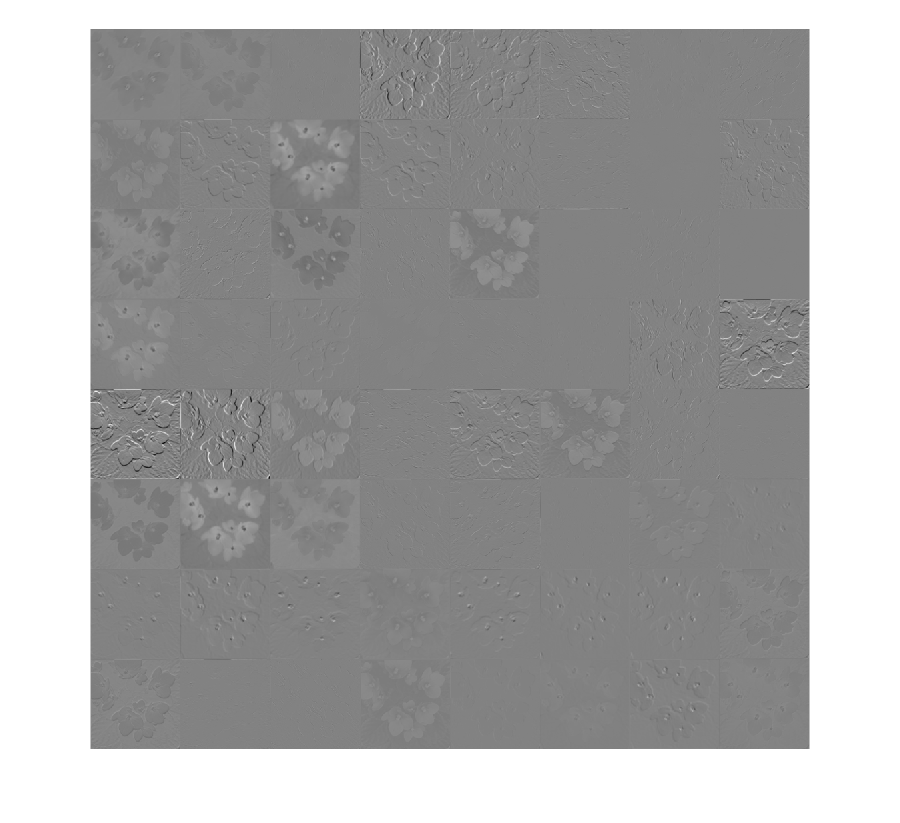

flwrImage = imread("../data/violet.jpg");
actvn = activations(net, flwrImage, "conv1-7x7_s2");
montage(mat2gray(actvn))

## Task 1

You have used the `"conv1-7x7_s2"` layer to extract features. The activations from a layer are the output of that layer. You can learn more about the activations by investigating the layer's properties.

These properties can be displayed by accessing any individual layer in a network. You can access the *n*th layer using:

`layers``(``n``)`

ly = layers(2)

ly =   Convolution2DLayer with properties:

              Name: 'conv1-7x7_s2'

   Hyperparameters
        FilterSize: [7 7]
       NumChannels: 3
        NumFilters: 64
            Stride: [2 2]
    DilationFactor: [1 1]
       PaddingMode: 'manual'
       PaddingSize: [3 3 3 3]
      PaddingValue: 0

   Learnable Parameters
           Weights: [7×7×3×64 single]
              Bias: [1×1×64 single]

  Show all properties


## Task 2

The convolution layer has *hyperparameters* and *learnable parameters*. Hyperparameters are set when the network is created and do not change during training. Learnable parameters are updated during training.

The weights of this convolution layer are stored in a 4-D array. The size of the fourth dimension, 64, is the number of channels.

To view all channels for a layer, you first need to get the activations.

actvn = activations(net, flwrImage, "inception_3b-output");

## Task 3

Each activation can take any value, so it is useful to scale the activations before you display them. You can normalize the activations using the function `mat2gray`.

actvnGray = mat2gray(actvn);

## Task 4

The `montage` function will display multiple images together. You can use the grayscale activations as input to the function.

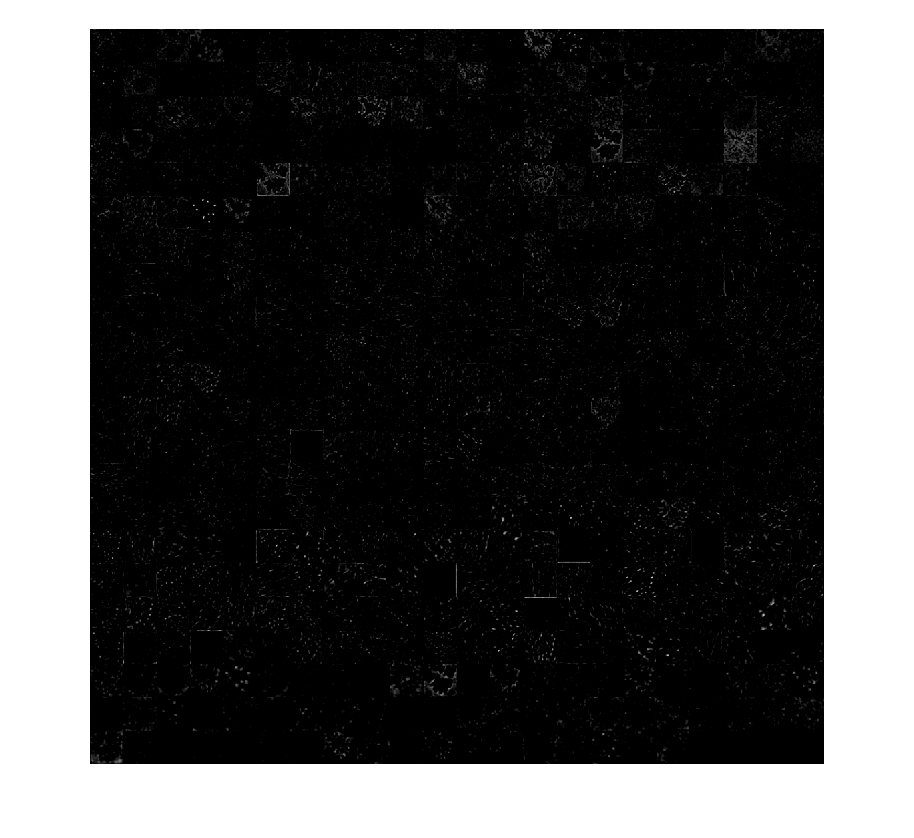

montage(actvnGray)

## Task 5

There is one image displayed for each of the 480 channels from the `"inception_3b-output"` layer. Generally, each of these channels contains one feature that is used for classification deeper in the architecture.

The activated areas in the images are a lot smaller, so the montage appears very dark. To zoom in on the images, you can open a figure window by clicking the arrow button in the upper-right corner of the output.

The next layer is a pooling layer. You can see the features that are used for classification by visualizing these activations.

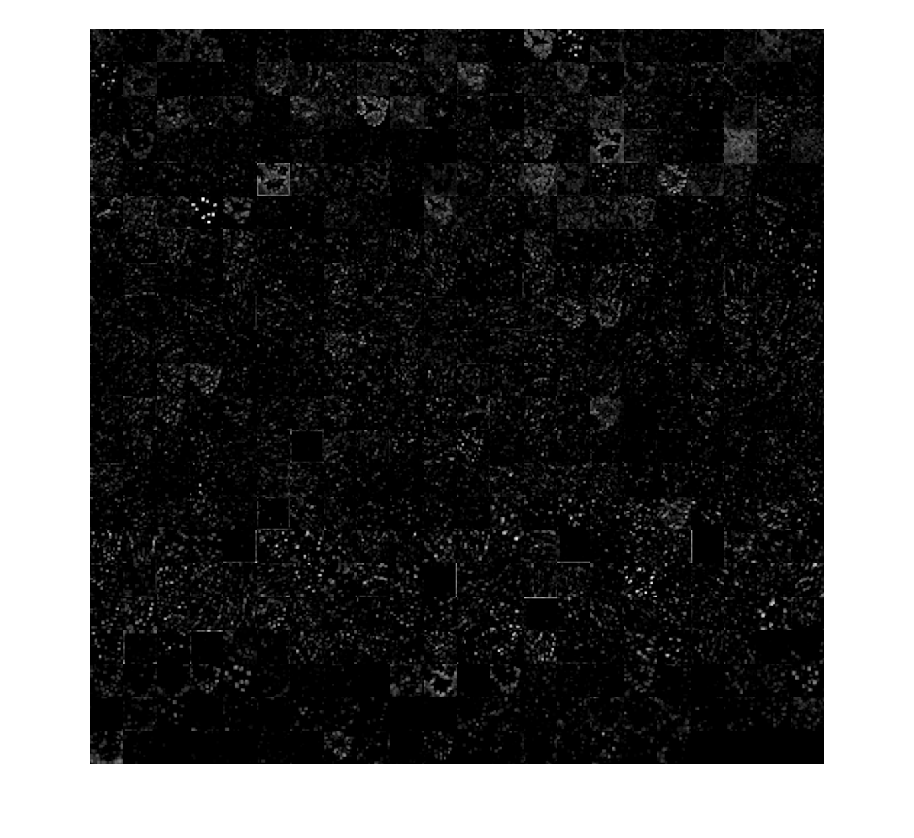

actvnPool = activations(net, flwrImage, "pool3-3x3_s2");
actvnPool = mat2gray(actvnPool);
montage(actvnPool);